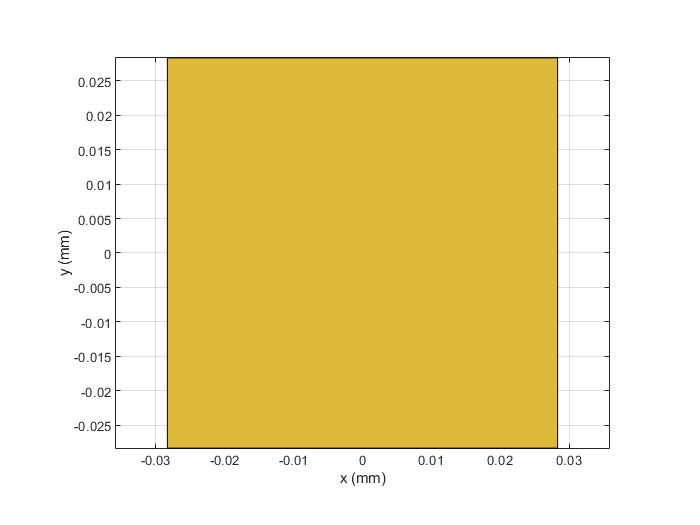

% GROUNDPLANE

grdplaneLength = 56.7e-3;
grdplaneWidth = 56.7e-3;

groundplane = antenna.Rectangle('Length',grdplaneLength,'Width',grdplaneWidth);
show(groundplane);

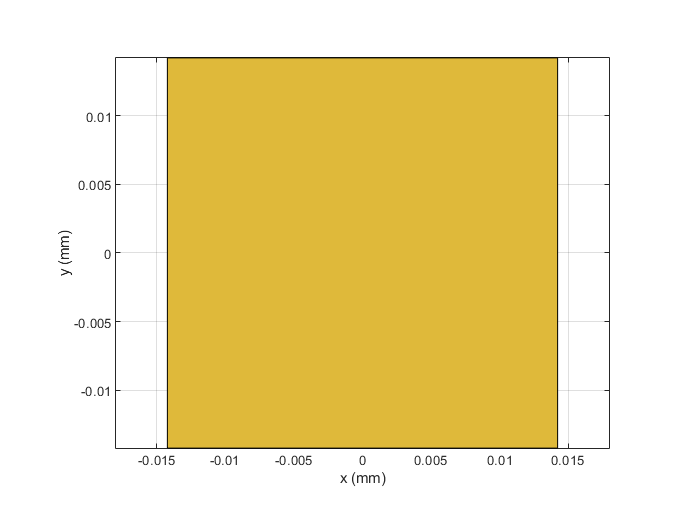


%MINOR PATCH (WITHOUT SLOT FOR FEED)
width = 28.45e-3;
length = 28.45e-3;

minorPatch = antenna.Rectangle('Length',length,'Width',width);
show(minorPatch);

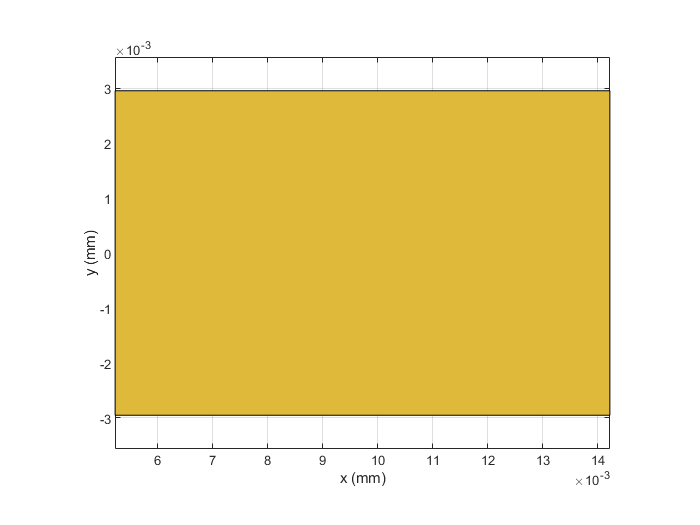


%NOTCH (SLOT FOR FEED)
% notchLength = 9e-3 -  (grdplaneLength/2 - length/2);
notchLength = 9e-3;
notchWidth =  5.9e-3;
notchSlotCenter = length/2 - notchLength/2;
notchSlot = antenna.Rectangle('Length',notchLength,'Width',notchWidth,'Center',[notchSlotCenter 0]);
 show(notchSlot);

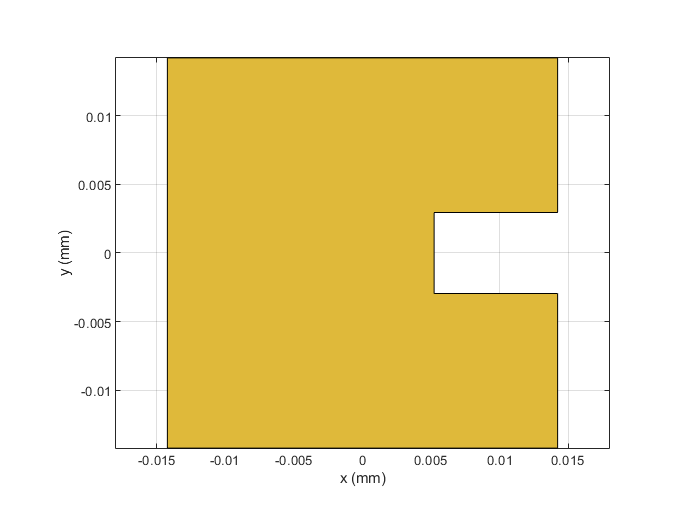


% MINOR PATCH + NOTCH
majorPatch = minorPatch - notchSlot;
 show(majorPatch);

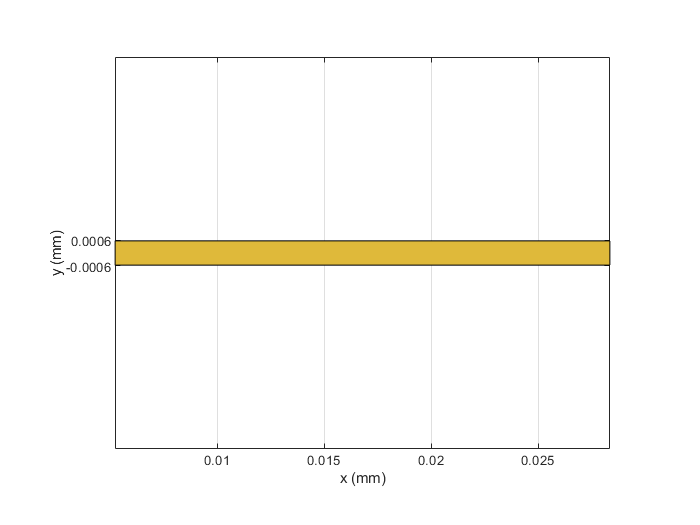


%FEED LINE
feedlinewidth = 1.137e-3;
feedlineLength = 9e-3  + grdplaneLength/2 - length/2;
feedlineCenter = length/2 - notchLength + feedlineLength/2;
feedline = antenna.Rectangle('Length',feedlineLength,'Width',feedlinewidth,'Center',[feedlineCenter 0]);
show(feedline);

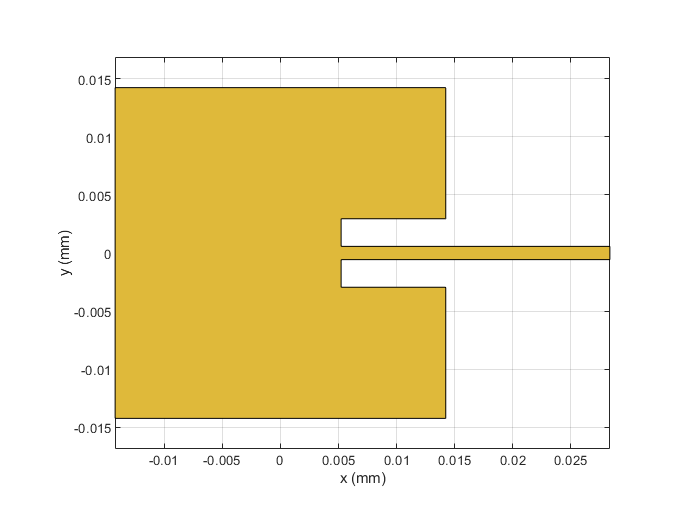


%THE FINAL DESIGN FOR PATCH 
FinalPatch = majorPatch + feedline;
 show(FinalPatch)


d = dielectric('FR4');
d.Thickness = 1.6e-3;
d.EpsilonR = 4.4;

patching = pcbStack;
patching.BoardShape = groundplane;
patching.BoardThickness = 0.035e-3;
patching.Layers = {FinalPatch,d,groundplane};
patching.FeedLocations = [0.02625 0 1 3]

patching =   pcbStack with properties:

              Name: 'MyPCB'
          Revision: 'v1.0'
        BoardShape: [1×1 antenna.Rectangle]
    BoardThickness: 3.5000e-05
            Layers: {[1×1 antenna.Polygon]  [1×1 dielectric]  [1×1 antenna.Rectangle]}
     FeedLocations: [0.0262 0 1 3]
      FeedDiameter: 1.0000e-03
      ViaLocations: []
       ViaDiameter: []
      FeedViaModel: 'strip'
       FeedVoltage: 1
         FeedPhase: 0
              Tilt: 0
          TiltAxis: [1 0 0]
              Load: [1×1 lumpedElement]


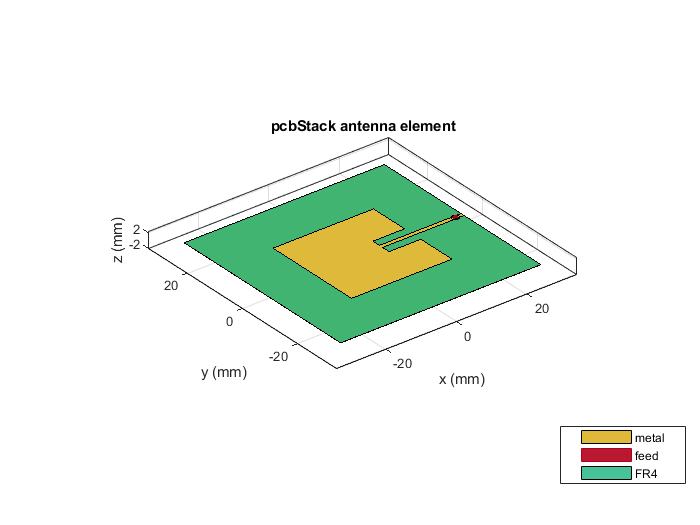

show(patching)

s = sparameters(patching,linspace(2e9,5e9,20))

s =   sparameters: S-parameters object

       NumPorts: 1
    Frequencies: [20×1 double]
     Parameters: [1×1×20 double]
      Impedance: 50

  rfparam(obj,i,j) returns S-parameter Sij


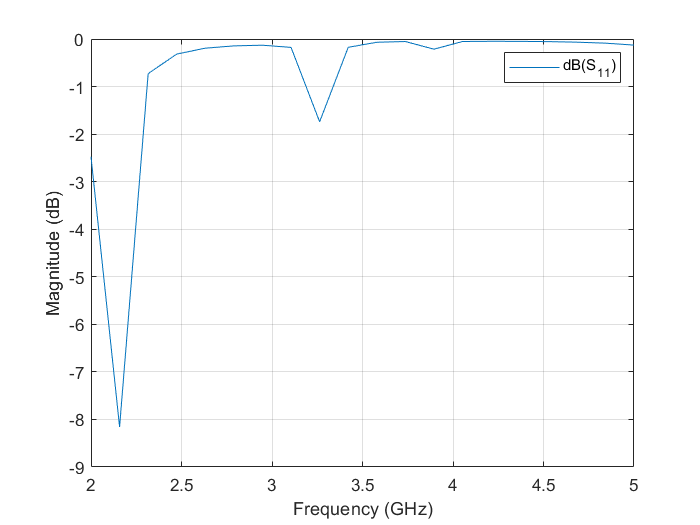

rfplot(s)